HW2

ruiyangz

Question1

a) a divided difference approach test

x = [0 1 2];
y = [1 3 2];
a = divided_diff_coeffs(x, y);
p = newton_eval(x, a, 1.5)

p = 2.8750

b) cos nterpolate

x = [0, 1/8, 1/4, 3/8, 1/2]

x =          0    0.1250    0.2500    0.3750    0.5000


y = cos(pi * x)

y =     1.0000    0.9239    0.7071    0.3827    0.0000



a = divided_diff_coeffs(x, y);

xstar = 3/10;

p_interp = newton_eval(x, a, xstar);

f_true = cos(pi * xstar);

% Error
err = abs(f_true - p_interp);

% Display results
fprintf('Interpolation of cos(pi*x) at x = %.2f\n', xstar);

Interpolation of cos(pi*x) at x = 0.30


fprintf('Interpolated value p(x) = %.8f\n', p_interp);

Interpolated value p(x) = 0.58785675


fprintf('True value f(x) = %.8f\n', f_true);

True value f(x) = 0.58778525


fprintf('Absolute error = %.3e\n', err);

Absolute error = 7.150e-05


c) function 2 / (1+9x^2)

f  = @(x) 2 ./ (1 + 9*x.^2);

x0 = 0.07;                      % evaluation point
ns = [2, 4, 40];                % degrees n

approx  = zeros(numel(ns),1);   % p_n(x0)
trueval = f(x0) * ones(numel(ns),1);
abserr  = zeros(numel(ns),1);

for t = 1:numel(ns)
    n = ns(t);
    xi = linspace(-1, 1, n+1);          % xi = 2*i/n - 1
    yi = f(xi);
    a  = divided_diff_coeffs(xi, yi);   % Newton DD coefficients
    approx(t) = newton_eval(xi, a, x0); % p_n(x0)
    abserr(t) = abs(approx(t) - trueval(t));
end

% Print a neat table
fprintf('\nPart (c): Interpolation of f(x)=2/(1+9x^2) at x0=%.4f\n', x0);


Part (c): Interpolation of f(x)=2/(1+9x^2) at x0=0.0700


fprintf('   n        p_n(x0)          f(x0)          |error|\n');

   n        p_n(x0)          f(x0)          |error|


for t = 1:numel(ns)
    fprintf('%4d   %14.10f  %14.10f   %10.3e\n', ns(t), approx(t), trueval(t), abserr(t));
end

   2     1.9911800000    1.9155253328    7.565e-02
   4     1.9668750652    1.9155253328    5.135e-02
  40     1.9155253271    1.9155253328    5.687e-09


d) Numerical max interpolation error on [-1,1]

f  = @(x) 2 ./ (1 + 9*x.^2);
ns = [2 4 6 8 10 12 14 16 18 20 40];

xx = linspace(-1, 1, 20001);         % ~2e4 points
fx = f(xx);

En = zeros(numel(ns),1);

for t = 1:numel(ns)
    n  = ns(t);
    xi = linspace(-1, 1, n+1);       % equispaced nodes (same as part (c))
    yi = f(xi);
    a  = divided_diff_coeffs(xi, yi);

    % Evaluate interpolant on the fine grid
    % (arrayfun calls newton_eval at each xx)
    pxx = arrayfun(@(z) newton_eval(xi, a, z), xx);

    % Max absolute error on the grid
    En(t) = max(abs(fx - pxx));
end

% Print a neat table
fprintf('\nPart (d): Max interpolation error En on [-1,1]\n');


Part (d): Max interpolation error En on [-1,1]



fprintf('   n            En (max |f - p_n|)\n');

   n            En (max |f - p_n|)



for t = 1:numel(ns)
    fprintf('%4d      %14.6e\n', ns(t), En(t));
end

   2        9.350889e-01
   4        5.963194e-01
   6        6.302535e-01
   8        7.681906e-01
  10        9.996674e-01
  12        1.351557e+00
  14        1.873958e+00
  16        2.645197e+00
  18        3.784085e+00
  20        5.469649e+00
  40        2.908908e+02


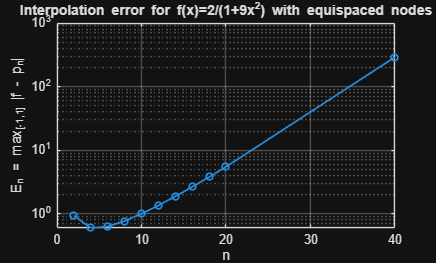


% Convergence plot
figure; semilogy(ns, En, '-o', 'LineWidth', 1.3, 'MarkerSize', 5);
grid on;
xlabel('n');
ylabel('E_n = max_{[-1,1]} |f - p_n|');
title('Interpolation error for f(x)=2/(1+9x^2) with equispaced nodes');